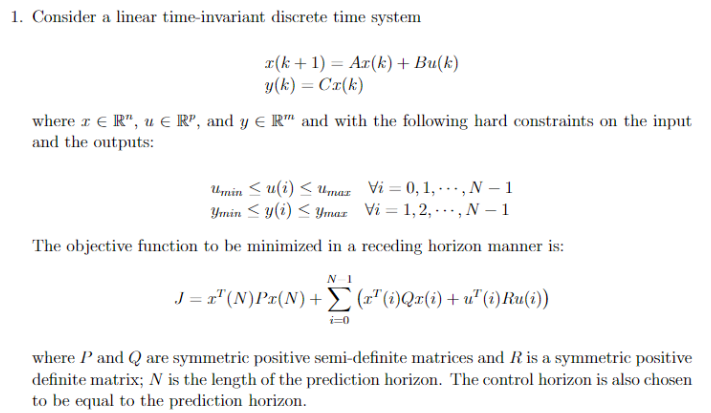

## Problem setup

clc;
clear;
addpath simMPC

dT = 0.1;
N = 10;
max_iter = 10;

A = [1 0 0;1 2 0;1 2 3].*dT;
A_d = A.*dT + eye(3);
B = ones(3,2);
B_d = B.*dT;
C = eye(3,3);

Q_i = 1e5*eye(3,3);
R_i = 0.1*eye(2,2);
P = 1e6*eye(3,3);

p = size(B,2);
m = size(C,2);



## Define constraints

% constraints
%u_min = [-3; -5]; u_max = [5; 5];
%y_min = -5*ones(m,1); y_max = 5*ones(m,1);

% no constraints
u_min = []; u_max = [];
y_min = []; y_max = [];


## **Get QP Matrices**

% get QP matrices
[F, G, A_ineq, b_ineq, b_ineq_x0] = get_QP(A_d,B_d,C,P,Q_i,R_i,N,u_min,u_max,y_min,y_max);


## **Run MPC with quadprog**

%% simulate MPC controller
X = []; U = []; T = [];
x0 = [1;1;1];
x = x0; t = 0;
for i = 1:max_iter
    T = [T, t];
    if(isempty(A_ineq))
        u = do_MPC(G,x'*F',[],[],p);
    else
        u = do_MPC(G,x'*F',A_ineq,b_ineq+b_ineq_x0*x,p);
    end
    X = [X, x];
    x = A*x + B*u;
    U = [U, u]; t = i*dT;
end 

## Plots

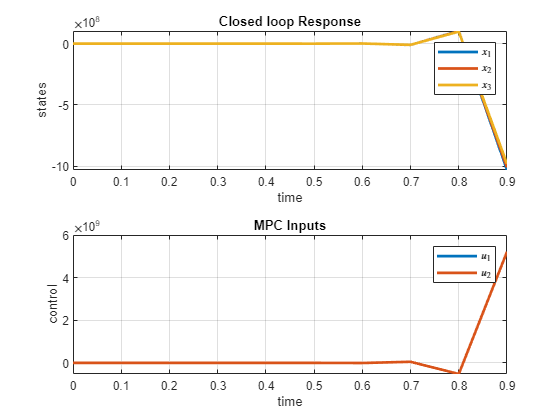

% plot
tiledlayout('flow')
nexttile
plot(T,X, 'LineWidth',2); grid on;
title(sprintf('Closed loop Response'))
ylabel('states')
xlabel ('time');
LEG = legend('$x_1$', '$x_2$', '$x_3$');
set(LEG,'interpreter','latex')
nexttile
plot(T,U,'LineWidth',2); grid on;
title(sprintf('MPC Inputs'))
ylabel('control')
xlabel ('time');
LEG = legend('$u_1$', '$u_2$');
set(LEG,'interpreter','latex')